Creating Gaussian data

% ensure each random generation is the same for testing purposes
rng('default');

mu = [0 0 0];
sigma = [1 0 0;0 1 0;0 0 1];

% generate gaussian with k samples and d dimensions
y = Gaussian(3,1000, mu, sigma);
% mean
m = mean(y);
% covariance
c = cov(y);

disp("Generation of normal distribution");

Generation of normal distribution


disp("mean: ");

mean: 


disp(m);

   -0.0326    0.0369    0.0383



disp("covariance: ");

covariance: 


disp(c);

    0.9979   -0.0093    0.0283
   -0.0093    0.9972    0.0519
    0.0283    0.0519    1.0110



disp(" ");

Creating gaussian with specified mean and covariance

mu_A = [0 4 7];
sigma_A = [6.5000 2.1651 1.2500; 2.1651 5.1250 2.3816; 1.2500 2.3816 2.3750];

mu_B = [10 5 5];
sigma_B = [3.0814 0.4331 -1.4481;0.4331 0.94336 -0.6456;-1.4481 -0.6456 1.2880];

mu_C = [- 2 -5 -5];
sigma_C = [6.8928 -1.3750 3.1945;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];

% generate gaussian with k samples and d dimensions
y_A = Gaussian(3,1000, mu_A, sigma_A);
% specified mean
m_A = mean(y_A);
% specified covariance
c_A = cov(y_A);

% generate gaussian with k samples and d dimensions
y_B = Gaussian(3,1000, mu_B, sigma_B);
% specified mean
m_B = mean(y_B);
% specified covariance
c_B = cov(y_B);

% generate gaussian with k samples and d dimensions
y_C = Gaussian(3,1000, mu_C, sigma_C);
% specified mean
m_C = mean(y_C);
% specified covariance
c_C = cov(y_C);

disp("Specified mean: mu A");

Specified mean: mu A


disp(m_A);

   -0.0148    3.9419    6.8983



disp("Specified covariance: sigma A");

Specified covariance: sigma A


disp(c_A);

    6.5074    2.2048    1.2856
    2.2048    4.9124    2.2579
    1.2856    2.2579    2.3269



disp(" ");


disp("Specified mean: mu B");

Specified mean: mu B


disp(m_B);

    9.9843    4.9765    4.9783



disp("Specified covariance: sigma B");

Specified covariance: sigma B


disp(c_B);

    2.8684    0.4849   -1.4326
    0.4849    0.9630   -0.6715
   -1.4326   -0.6715    1.3097



disp(" ");


disp("Specified mean: mu C");

Specified mean: mu C


disp(m_C);

   -2.0751   -4.9829   -5.0794



disp("Specified covariance: sigma C");

Specified covariance: sigma C


disp(c_C);

    6.1604   -1.2160    3.0739
   -1.2160    3.0026    0.6143
    3.0739    0.6143    3.7366



disp(" ");

The Matlab's computed covariance matrix for our Gaussian generated data will not exactly match the covariance  we prescribed, because we are drawing finite number of samples from a normal distribution and the samples cannot fully represent the normal distribution. So when K < $$\infty$$, we can have mu getting closer to 0 and sigma getting closer to identity matrix by drawing increasing number of samples from the normal distribution, but they will not exactly match.

Correcting the problem stated above

y_correct = Gaussian_correct(3,1000, mu, sigma);

Before subtracting mean and Whitening Transform: 
mean: 
   -0.0100   -0.0063    0.0046

Covariance: 
    0.9857   -0.0106    0.0668
   -0.0106    0.9324   -0.0332
    0.0668   -0.0332    1.0517

 


%mean
m_correct = mean(y_correct);
%covariance
c_correct = cov(y_correct);
disp("After subtracting mean and Whitening Transform: ");

After subtracting mean and Whitening Transform: 


disp("mean: ");

mean: 


disp(m_correct);

   1.0e-16 *

    0.3197    0.0355    0.2529



disp("Covariance: ");

Covariance: 


disp(c_correct);

    1.0000    0.0000   -0.0000
    0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000



disp(" ");

testings

yA_correct = Gaussian_correct(3,1000, mu_A, sigma_A);

Before subtracting mean and Whitening Transform: 
mean: 
   -0.0197    3.9514    7.0035

Covariance: 
    6.5846    2.4818    1.4289
    2.4818    5.0211    2.3646
    1.4289    2.3646    2.4218

 


% specifed mean class A
mA_correct = mean(yA_correct);
% specifed covariance class A
cA_correct = cov(yA_correct);
disp("After subtracting mean and Whitening Transform: ");

After subtracting mean and Whitening Transform: 


disp("Class A mean: ");

Class A mean: 


disp(mA_correct);

   -0.0000    4.0000    7.0000



disp("Class A Covariance: ");

Class A Covariance: 


disp(cA_correct);

    6.5000    2.1651    1.2500
    2.1651    5.1250    2.3816
    1.2500    2.3816    2.3750



disp(" ");


yB_correct = Gaussian_correct(3,1000, mu_B, sigma_B);

Before subtracting mean and Whitening Transform: 
mean: 
   10.0043    5.0315    4.9869

Covariance: 
    3.2847    0.4788   -1.5479
    0.4788    0.9020   -0.6305
   -1.5479   -0.6305    1.3535

 


% specifed mean for class B
mB_correct = mean(yB_correct);
% specifed covariance class B
cB_correct = cov(yB_correct);
disp("After subtracting mean and Whitening Transform: ");

After subtracting mean and Whitening Transform: 


disp("Class B mean: ");

Class B mean: 


disp(mB_correct);

   10.0000    5.0000    5.0000



disp("Class B Covariance: ");

Class B Covariance: 


disp(cB_correct);

    3.0814    0.4331   -1.4481
    0.4331    0.9434   -0.6456
   -1.4481   -0.6456    1.2880



disp(" ");


yC_correct = Gaussian_correct(3,1000, mu_C, sigma_C);

Before subtracting mean and Whitening Transform: 
mean: 
   -2.0453   -4.9305   -5.0126

Covariance: 
    6.8877   -1.1449    3.3449
   -1.1449    3.3111    0.7929
    3.3449    0.7929    3.8693

 


% specifed mean for class C
mC_correct = mean(yC_correct);
% specifed covariance class C
cC_correct = cov(yC_correct);
disp("After subtracting mean and Whitening Transform: ");

After subtracting mean and Whitening Transform: 


disp("Class C mean: ");

Class C mean: 


disp(mC_correct);

   -2.0000   -5.0000   -5.0000



disp("Class C Covariance: ");

Class C Covariance: 


disp(cC_correct);

    6.8928   -1.3750    3.1945
   -1.3750    3.3572    0.6945
    3.1945    0.6945    3.7500



disp(" ")

ploting the dataset with ellipsoid

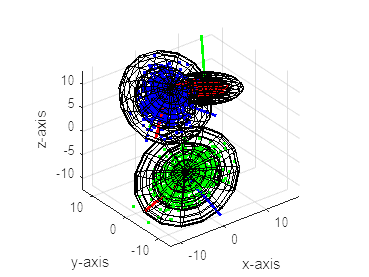

n = 15;
% Plot class A
mu = mu_A;
sigma = sigma_A;
[U,S,V] = svd(sigma);
S = sqrt(S);


% Class A, 1x standard deviation
[x1,y1,z1]=ellipsoid(0, 0, 0, sqrt(sigma(1,1)), sqrt(sigma(2,2)), sqrt(sigma(3,3)), n);
data_correlated1 = [x1(:), y1(:), z1(:)]*S*U' + repmat(mu,(n+1)^2,1);
data1=transform_ellipsoid(data_correlated1,n,mu,sqrt(S),U);
x1 = reshape(data1(:, 1), size(x1));
y1 = reshape(data1(:, 2), size(y1));
z1 = reshape(data1(:, 3), size(z1));
    
% Class A, 2x standard deviation
[x2,y2,z2]=ellipsoid(0, 0, 0, 2*sqrt(sigma(1,1)), 2*sqrt(sigma(2,2)), 2*sqrt(sigma(3,3)), n);
data_correlated2 = [x2(:), y2(:), z2(:)]*S*U' + repmat(mu,(n+1)^2,1);
data2=transform_ellipsoid(data_correlated2,n,mu,2*sqrt(S),U);
x2 = reshape(data2(:, 1), size(x2));
y2 = reshape(data2(:, 2), size(y2));
z2 = reshape(data2(:, 3), size(z2));
    
% Class A, 3x standard deviation
[x3,y3,z3]=ellipsoid(0, 0, 0, 3*sqrt(sigma(1,1)), 3*sqrt(sigma(2,2)), 3*sqrt(sigma(3,3)), n);
data_correlated3 = [x3(:), y3(:), z3(:)]*S*U' + repmat(mu,(n+1)^2,1);
data3 = transform_ellipsoid(data_correlated3,n,mu,3*sqrt(S),U);
x3 = reshape(data3(:, 1), size(x3));
y3 = reshape(data3(:, 2), size(y3));
z3 = reshape(data3(:, 3), size(z3));

% Plot class B
mu = mu_B;
sigma = sigma_B;
[U,S,V] = svd(sigma);
S = sqrt(S);


% Class B, 1x standard deviation
[x4,y4,z4]=ellipsoid(0, 0, 0, sqrt(sigma(1,1)), sqrt(sigma(2,2)), sqrt(sigma(3,3)), n);
data_correlated4 = [x4(:), y4(:), z4(:)]*S*U' + repmat(mu,(n+1)^2,1);
data4=transform_ellipsoid(data_correlated4,n,mu,sqrt(S),U);
x4 = reshape(data4(:, 1), size(x4));
y4 = reshape(data4(:, 2), size(y4));
z4 = reshape(data4(:, 3), size(z4));
    
    
% Class B, 2x standard deviation
[x5,y5,z5]=ellipsoid(0, 0, 0,  2*sqrt(sigma(1,1)), 2*sqrt(sigma(2,2)), 2*sqrt(sigma(3,3)), n);
data_correlated5 = [x5(:), y5(:), z5(:)]*S*U' + repmat(mu,(n+1)^2,1);
data5=transform_ellipsoid(data_correlated5,n,mu,2*sqrt(S),U);
x5 = reshape(data5(:, 1), size(x5));
y5 = reshape(data5(:, 2), size(y5));
z5 = reshape(data5(:, 3), size(z5));
    
% Class B, 3x standard deviation
[x6,y6,z6]=ellipsoid(0, 0, 0, 3*sqrt(sigma(1,1)), 3*sqrt(sigma(2,2)), 3*sqrt(sigma(3,3)), n);
data_correlated6 = [x6(:), y6(:), z6(:)]*S*U' + repmat(mu,(n+1)^2,1);
data6 = transform_ellipsoid(data_correlated6,n,mu,3*sqrt(S),U);
x6 = reshape(data6(:, 1), size(x6));
y6 = reshape(data6(:, 2), size(y6));
z6 = reshape(data6(:, 3), size(z6));

% Plot class C
mu = mu_C;
sigma = sigma_C;
[U,S,V] = svd(sigma);
S = sqrt(S);

% Class C, 1x standard deviation
[x7,y7,z7]=ellipsoid(0, 0, 0, sqrt(sigma(1,1)), sqrt(sigma(2,2)), sqrt(sigma(3,3)), n);
data_correlated7 = [x7(:), y7(:), z7(:)]*S*U' + repmat(mu,(n+1)^2,1);
data7=transform_ellipsoid(data_correlated7,n,mu,sqrt(S),U);
x7 = reshape(data7(:, 1), size(x7));
y7 = reshape(data7(:, 2), size(y7));
z7 = reshape(data7(:, 3), size(z7));
    
    
% Class C, 2x standard deviation
[x8,y8,z8]=ellipsoid(0, 0, 0, 2*sqrt(sigma(1,1)), 2*sqrt(sigma(2,2)), 2*sqrt(sigma(3,3)), n);
data_correlated8 = [x8(:), y8(:), z8(:)]*S*U' + repmat(mu,(n+1)^2,1);
data8=transform_ellipsoid(data_correlated8,n,mu,2*sqrt(S),U);
    
x8 = reshape(data8(:, 1), size(x8));
y8 = reshape(data8(:, 2), size(y8));
z8 = reshape(data8(:, 3), size(z8));
    
% Class C, 3x standard deviation
[x9,y9,z9]=ellipsoid(0, 0, 0, 3*sqrt(sigma(1,1)), 3*sqrt(sigma(2,2)), 3*sqrt(sigma(3,3)), n);
data_correlated9 = [x9(:), y9(:), z9(:)]*S*U' + repmat(mu,(n+1)^2,1);
data9 = transform_ellipsoid(data_correlated9,n,mu,3*sqrt(S),U);
x9 = reshape(data9(:, 1), size(x9));
y9 = reshape(data9(:, 2), size(y9));
z9 = reshape(data9(:, 3), size(z9));


figure
surf(x1,y1,z1);
hold on
surf(x2,y2,z2);
hold on
surf(x3,y3,z3);
hold on
surf(x4,y4,z4);
hold on
surf(x5,y5,z5);
hold on
surf(x6,y6,z6);
hold on
surf(x7,y7,z7);
hold on
surf(x8,y8,z8);
hold on
surf(x9,y9,z9);
axis equal
alpha 0
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')

length = 10;
plot_principal_axes(yA_correct,mu_A,length);
plot_principal_axes(yB_correct,mu_B,length);
plot_principal_axes(yC_correct,mu_C,length);


% Plot the data points of the 3 classes
scatter3(yA_correct(:,1),yA_correct(:,2),yA_correct(:,3),5,'blue','filled')
hold on
scatter3(yB_correct(:,1),yB_correct(:,2),yB_correct(:,3),5,'red','filled')
hold on
scatter3(yC_correct(:,1),yC_correct(:,2),yC_correct(:,3),5,'green','filled')
hold off

Functions

function x = Gaussian(D,K, mu, sigma) % function to create gaussian    
    data = randn(K,D);
    % singular decomposition of covariance
    [u,s,v] = svd(sigma);
    s = sqrt(s);
    % only use left or right singular vectors
    % use left here to create correlations
    x = data*s*u' + mu;
end

% function for correcting dataset 
function x = Gaussian_correct(D,K, mu, sigma)
    data = randn(K,D);
    % singular decomposition of covariance
    [u,s,v] = svd(sigma);
    s = sqrt(s);
    % only use left or right singular vectors
    % use left here to create correlations
    data_correlated = data*s*u' + mu;
    m = mean(data_correlated); % mean of data generated with specified mean
    c = cov(data_correlated); %covarinace of data generated with specified covarinace

    disp("Before subtracting mean and Whitening Transform: ");
    disp("mean: ");
    disp(m);
    disp("Covariance: ");
    disp(c);
    disp(" ");

    % subtracting mean
    x = data_correlated - m;

    % Whitening transformation
    % Peform eigenvalue/eigenvector decomposition
    [v,d] = eig(c);
    [ d_sorted , idx_sorted ] = sort( diag( d ) , 'descend' );
    w = v(:, idx_sorted);
    x = x * w * diag(1./sqrt(d_sorted));
    x = x*s*u' + mu;
end

function data = transform_ellipsoid(data_corr,n,mu,S,U)
    m = mean(data_corr); 
    c = cov(data_corr); 
    data_corr = data_corr -repmat(mu,(n+1)^2,1);

    [v,d] = eig(c);
    [ d_sorted , idx_sorted ] = sort( diag( d ) , 'descend' );
    w = v(:, idx_sorted);
    data_corr = data_corr * w * diag(1./sqrt(d_sorted));
    data = data_corr*S*U' + repmat(mu,(n+1)^2,1);
end
function plot_principal_axes(y,mu,length)
    y_new = y - repmat(mu,1000,1);
    [U_new, S_new, V_new] = svd(y_new);
    line([mu(1), mu(1) + length*V_new(1, 1)], [mu(2), mu(2) + length*V_new(2, 1)], [mu(3), mu(3) + length*V_new(3, 1)], 'Color', 'red', 'LineWidth', 2);
    line([mu(1), mu(1) + length*V_new(1, 2)], [mu(2), mu(2) + length*V_new(2, 2)], [mu(3), mu(3) + length*V_new(3, 2)], 'Color', 'blue', 'LineWidth', 2);
    line([mu(1), mu(1) + length*V_new(1, 3)], [mu(2), mu(2) + length*V_new(2, 3)], [mu(3), mu(3) + length*V_new(3, 3)], 'Color', 'green', 'LineWidth', 2);
end
